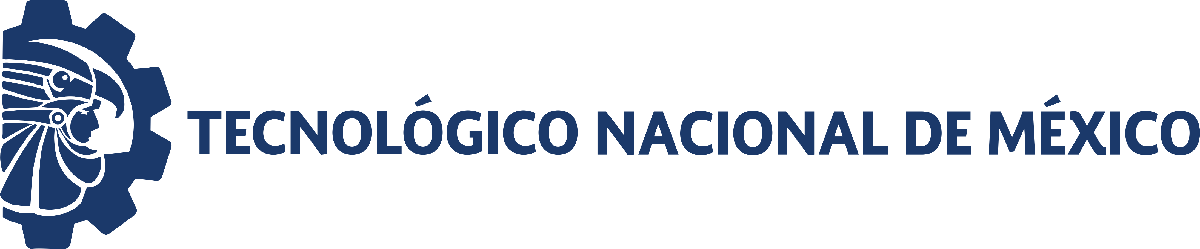                                 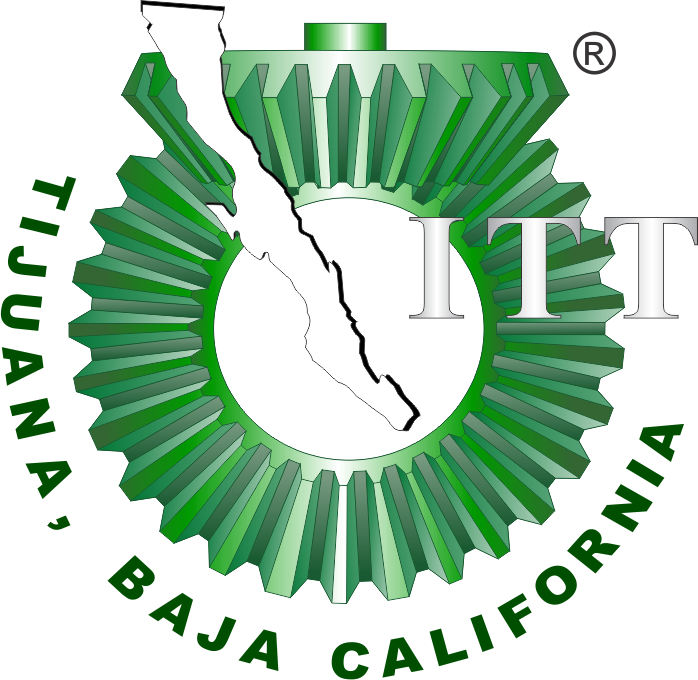

# Práctica 4: Regeneración de glóbulos rojos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

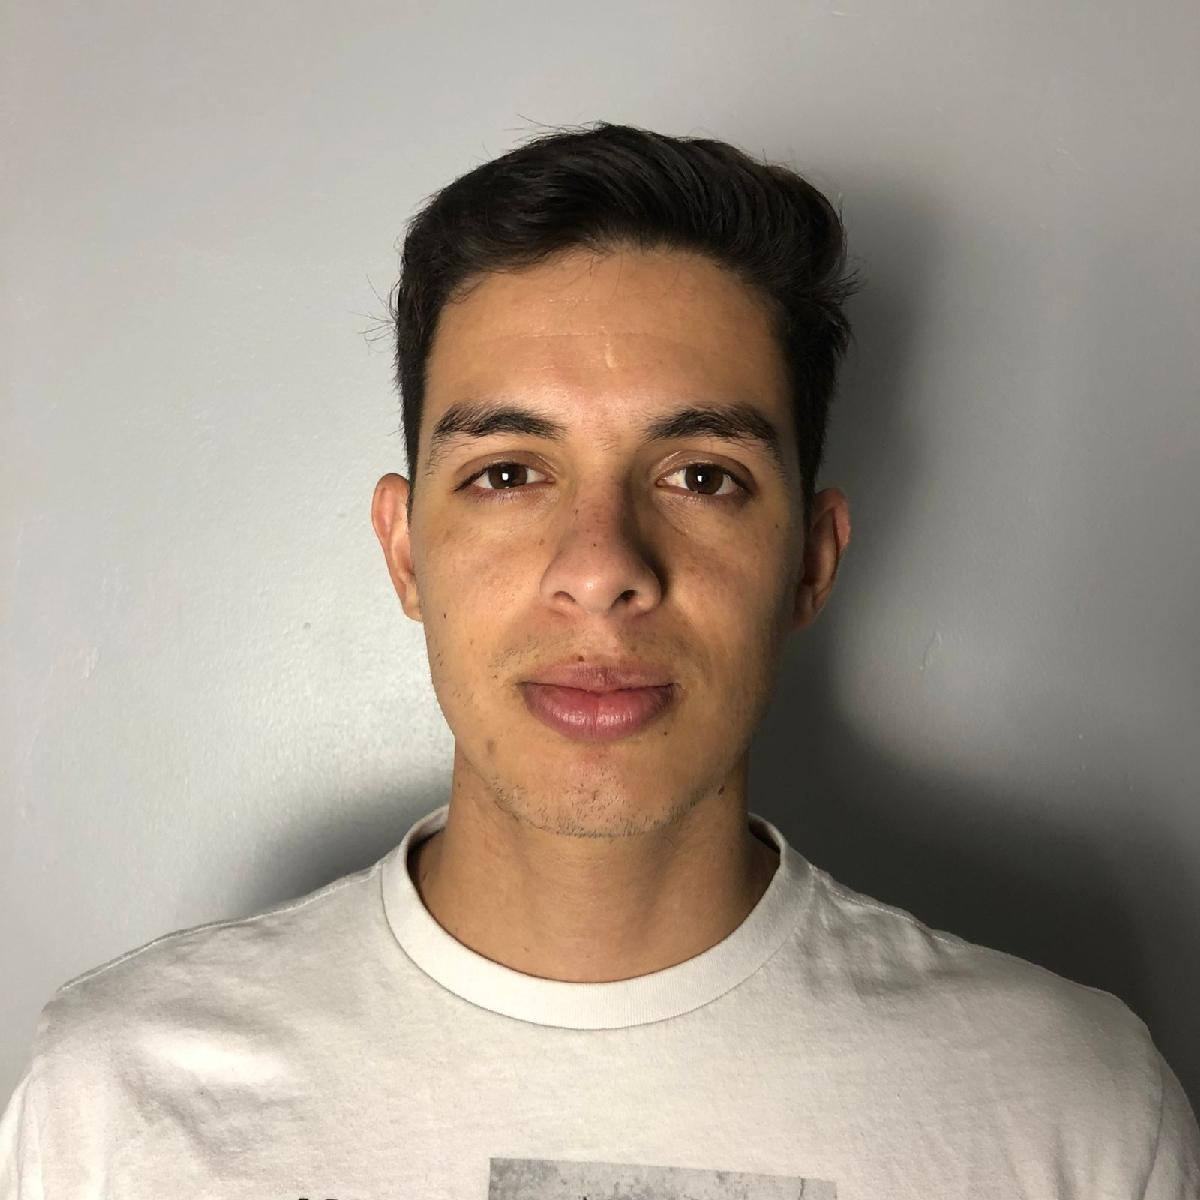

Nombre del alumno: Chizek Espinoza Josue

Número de control: 22212382

Correo institucional: l22212382**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulacion

clc; clear; format short; warning('off','all')
tend = 180; %Tiempo de la simulacion
dt = 1E-3; %Intervalo de integracion para el metodo de solucion 
n = round (tend/dt); %Cantidad de iteracciones para el metodo numerico

%Condiciones iniciales base para cada paciente
x1_0 = 59; x2_0 = 44; x3_0 =885; 

%Parametros particulares para cada paciente
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057];
beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed = 22212382;
rng(seed, "twister")

xmin = 0.99; xmax = 1.01;
interval = xmin + (xmax - xmin).*rand(numel(gamma),1);
%Condiciones iniciales para cada paciente
x1_0 = x1_0*interval; disp('x1_0 = '); disp(x1_0');...
x2_0 = x2_0*interval; disp('x2_0 = '); disp(x2_0');...
x3_0 = x3_0*interval; disp('x3_0 = '); disp(x3_0');

x1_0 = 
   58.6308   58.8573   59.2585   58.4723   58.6544   58.9227   59.1065   58.9352   58.5179   58.8068



x2_0 = 
   43.7246   43.8936   44.1928   43.6065   43.7422   43.9423   44.0795   43.9517   43.6404   43.8559



x3_0 = 
  879.4615  882.8598  888.8781  877.0843  879.8155  883.8403  886.5982  884.0281  877.7681  882.1014



## Caso: Sin transfución sanguinea [u(t) = 0]

u = zeros (n+1,1);
fig = 1;
for i=1:10
    [t,x1,x2,x3] = system (x1_0(i),x2_0(i), x3_0(i),beta(1),gamma(i),u,dt,tend);
    plotdata (t,x1,x2,x3,fig)
end

## Funcion: Con transfusion Sanguinea [u(t) = 1(t1,t2)]

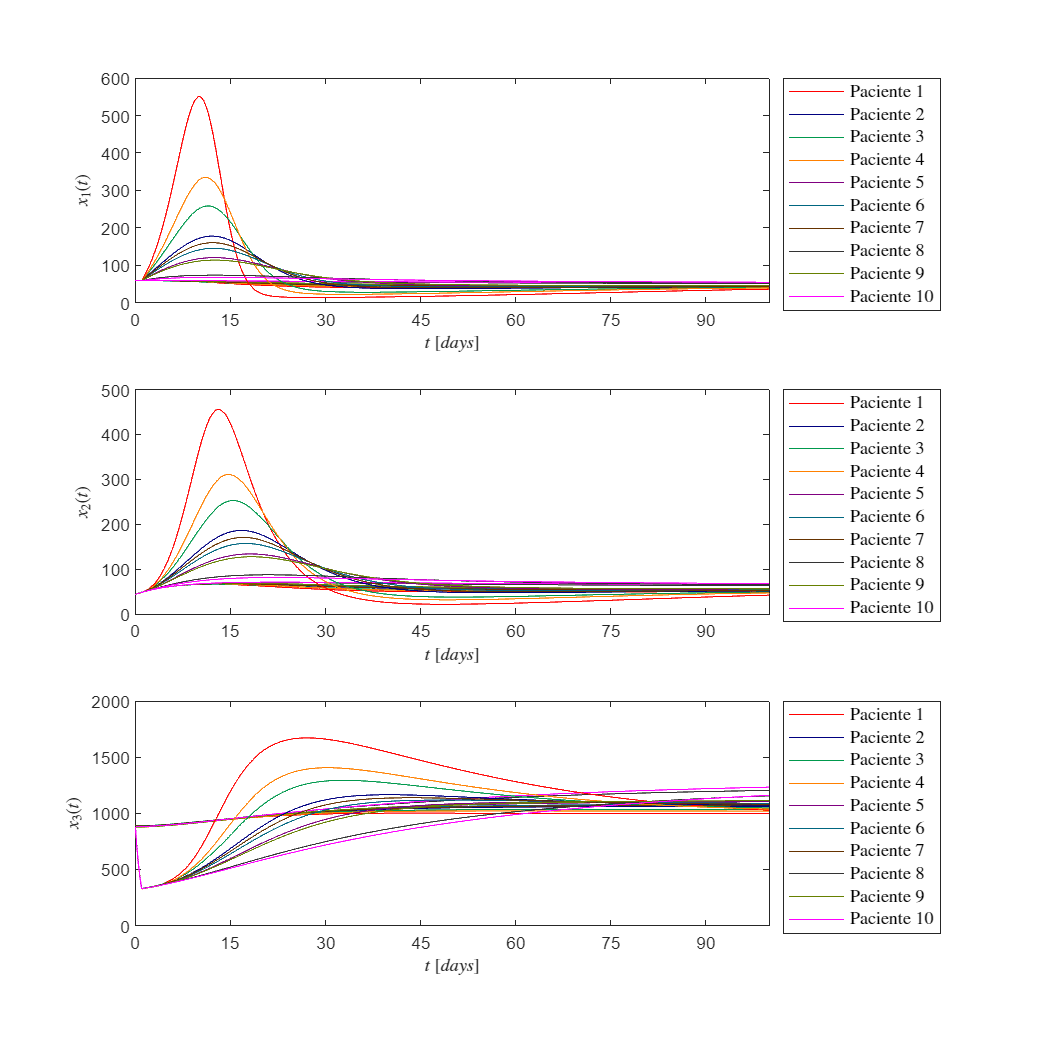

u = zeros(n+1,1); u(1:round(1/dt))=1;
fig = 2;
for i=1:10
    [t,x1,x2,x3] = system (x1_0(i),x2_0(i), x3_0(i),beta(1),gamma(i),u,dt,tend);
    plotdata (t,x1,x2,x3,fig)
end

## Funcion: Modelo Matematico


$$\dot{x_1 } =\beta \left(X_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$



$$\dot{x_2 } =\beta \left(X_0 -k_2 x_2 \right)$$



$$\dot{x_3 } =\beta \left(k_2 x_2 -\alpha x_3 \right)-u\left(t\right)x_3$$


## **Funcion **

function[t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
    Base = 885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
    t = (0:dt:tend)';
    n = round (tend/dt);
    x1 = zeros(n+1,1);x1(1) = x1_0;
    x2 = zeros(n+1,1);x2(1) = x2_0;
    x3 = zeros(n+1,1);x3(1) = x3_0;
    for i = 1:n%metodo de euler(diferencias finitas)
        x1(i+1) = x1(i)+(beta*(X0 - k1*x1(i)) + gamma*(Base - x3(i))*(1 - u(i))*x1(i)/Base)*dt;
        x2(i+1) = x2(i) + (beta* k1*x1(i)- k2*x2(i))*dt;
        x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) - u(i)*x3(i))*dt;

    end 
end


## **Función: Soluciones en el tiempo **

function plotdata(t,x1,x2,x3,fig)
    set(figure(fig),'Color', 'w')
    set(gcf,'Units', 'Centimeters', 'Position', [1,1,20,20])

        mycolors = [1.0, 0.0, 0.0;
            0.0, 0.0, 0.5;
            0.0, 0.6, 0.3;
            1.0, 0.5, 0.0;
            0.5, 0.0, 0.5;
            0.0, 0.4, 0.5;
            0.4, 0.2, 0.0;
            0.2, 0.2, 0.2;
            0.4, 0.5, 0.0;
            1.0, 0.0, 1.0];

    subplot(3,1,1)
    hold on ; grid off; box on; colororder(mycolors)
    plot(t,x1)
    xlabel ('$t$ $[days]$', 'Interpreter','latex', 'FontSize',10)
    ylabel ('$x_1(t)$','Interpreter','latex', 'FontSize',10)
    xlim([0 100]); xticks (0:15:180)
    L = legend('Paciente 1', 'Paciente 2', 'Paciente 3', 'Paciente 4', 'Paciente 5', 'Paciente 6', 'Paciente 7', 'Paciente 8', 'Paciente 9', 'Paciente 10');
     set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');

     subplot(3,1,2)
    hold on ; grid off; box on; colororder(mycolors)
    plot(t,x2)
    xlabel ('$t$ $[days]$', 'Interpreter','latex', 'FontSize',10)
    ylabel ('$x_2(t)$','Interpreter','latex', 'FontSize',10)
    xlim([0 100]); xticks (0:15:180)
     L = legend('Paciente 1', 'Paciente 2', 'Paciente 3', 'Paciente 4', 'Paciente 5', 'Paciente 6', 'Paciente 7', 'Paciente 8', 'Paciente 9', 'Paciente 10');
     set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');

     subplot(3,1,3)
    hold on ; grid off; box on; colororder(mycolors)
    plot(t,x3)
    xlabel ('$t$ $[days]$', 'Interpreter','latex', 'FontSize',10)
    ylabel ('$x_3(t)$','Interpreter','latex', 'FontSize',10)
    xlim([0 100]); xticks (0:15:180)
   L = legend('Paciente 1', 'Paciente 2', 'Paciente 3', 'Paciente 4', 'Paciente 5', 'Paciente 6', 'Paciente 7', 'Paciente 8', 'Paciente 9', 'Paciente 10');
     set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');


     if fig == 1
         exportgraphics(gcf, 'Caso Sin Transfusion.pdf', 'ContentType','vector')
     elseif fig == 2
          exportgraphics(gcf, 'Caso Con Transfusion.pdf', 'ContentType','vector')
     end

end